## Estimate model from square wave, validate with sine wave

Hyperparams

clear
trainingFile = "tower_crane_square_test_data.mat";
validationFile = "tower_crane_sine_test_data.mat";
output = "arm";

trainingStruct = load(trainingFile);
validationStruct = load(validationFile);

% sampling time
Ts = 0.002;

Preprocessing: cut off a few seconds

secondsToCutOff =4;
% like this because matlab passes by value
trainingStruct = cutoffBeginning(trainingStruct, Ts, secondsToCutOff);
validationStruct = cutoffBeginning(validationStruct, Ts, secondsToCutOff);
% set options appropriately
tfestOpt = tfestOptions;
ssestOpt = ssestOptions;
initialCondZero = false;
if secondsToCutOff == 0
  initialCondZero = true;
  tfestOpt.InitialCondition = 'zero';
  ssestOpt.InitialState = 'zero';  
end

load training and validation data

[t, y, u] = extractData(trainingStruct, output);
[t_val, y_val, u_val] = extractData(validationStruct, output);
data = iddata(y, u, Ts);
data_val = iddata(y_val, u_val, Ts);

% augment training data
extraTrainingData = false;
if extraTrainingData
    extraDataStruct = load("tower_crane_emile_lennart_data.mat");
    [to, yo, uo] = extractData(extraDataStruct, output);
    extraData = iddata(yo, uo, Ts);
    data = merge(data, extraData);
end

constants

N = length(t);
% why this line?
t = (0:Ts:(N-1)*Ts)';

Create data and estimate transfer function

numberPoles = 3

numberPoles = 3



%Gest = tfest(data, 3, 1, 0, opt)
% only specify number of poles
Gest = tfest(data, numberPoles, tfestOpt)

Gest =
 
  From input "u1" to output "y1":
     -68.04 s^2 + 94.87 s - 297.7
  -----------------------------------
  s^3 + 208.5 s^2 + 108 s + 3.273e-07
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: [64.9 26.69]%            
FPE: 0.07554, MSE: [0.01239 0.1131]              


See fit on training data

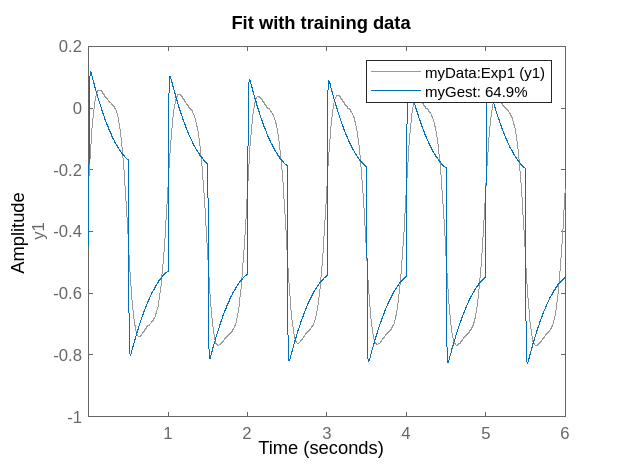

myCompare(data, Gest, initialCondZero)
title('Fit with training data')

See fit on validation data

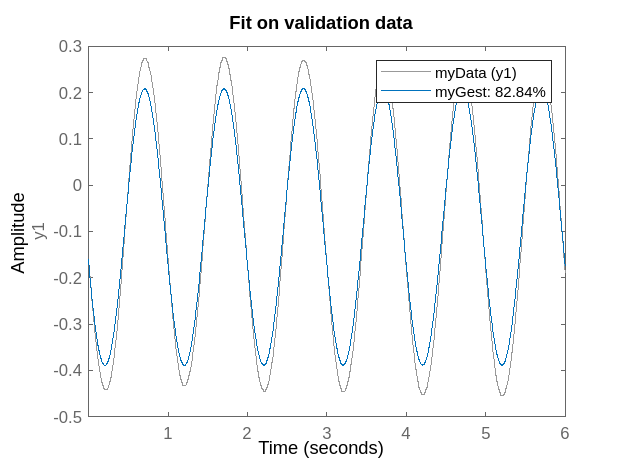

myCompare(data_val, Gest, initialCondZero)
title('Fit on validation data')

Estimate model with ssest

% telling initial state is zero in the options
Gss = ssest(data, 1:10, ssestOpt);
Gest_new = tf(Gss)

Gest_new =
 
  From input "u1" to output "y1":
     -0.02836 s^2 + 31.1 s + 91.95
  -----------------------------------
  s^3 + 6.825 s^2 + 18.49 s + 0.07342
 
Continuous-time transfer function.



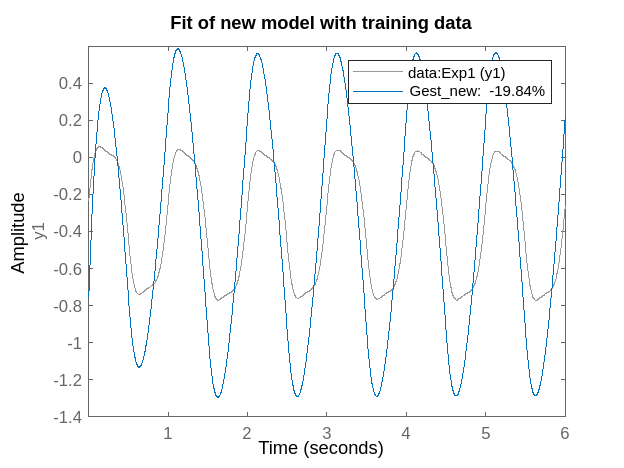

compare(data, Gest_new)
title('Fit of new model with training data')

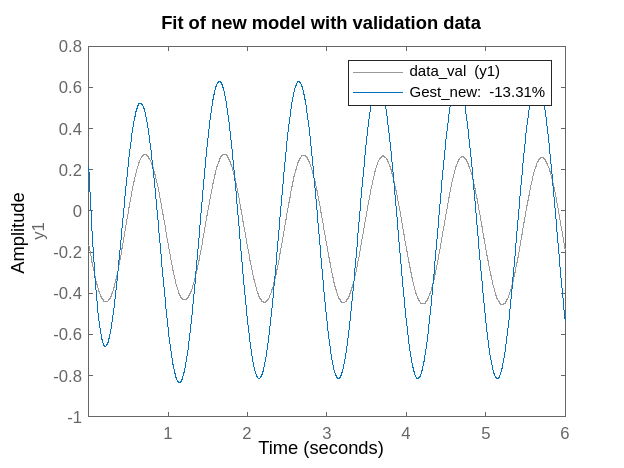

compare(data_val, Gest_new)
title('Fit of new model with validation data')

if we cut something off for training, compare the obtained model with the entire data

skipSec = 0

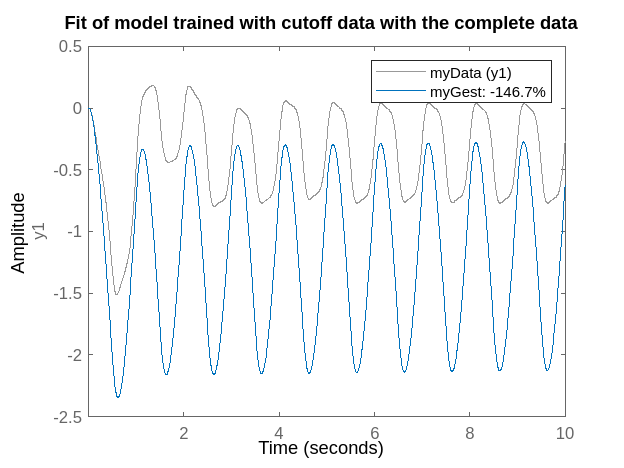

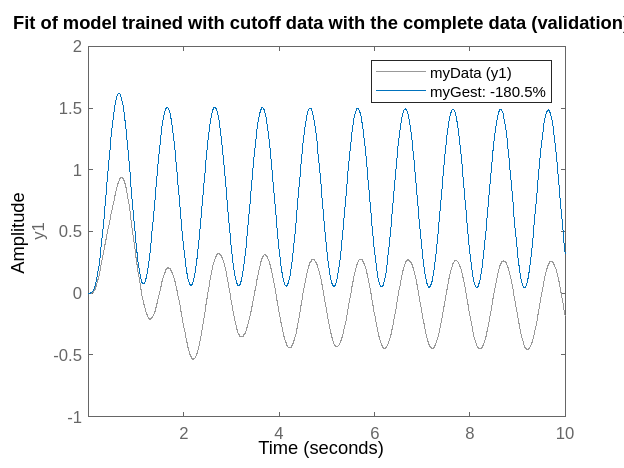

if not(initialCondZero) 
    skipSec = 0
    [t_c, y_c, u_c] = extractCompleteData(trainingStruct, output, Ts, skipSec);
    [t_c_val, y_c_val, u_c_val] = extractCompleteData(validationStruct, output, Ts, skipSec);
    % TODO modular if arm or pendulum
    data_c = iddata(y_c, u_c, Ts);
    data_c_val = iddata(y_c_val, u_c_val, Ts);
    figure
    myCompare(data_c, Gest_new, skipSec == 0)
    title('Fit of model trained with cutoff data with the complete data')
    
    figure
    myCompare(data_c_val, Gest_new, skipSec == 0)
    title('Fit of model trained with cutoff data with the complete data (validation)')
end

Sanity check : system response to constant zero input

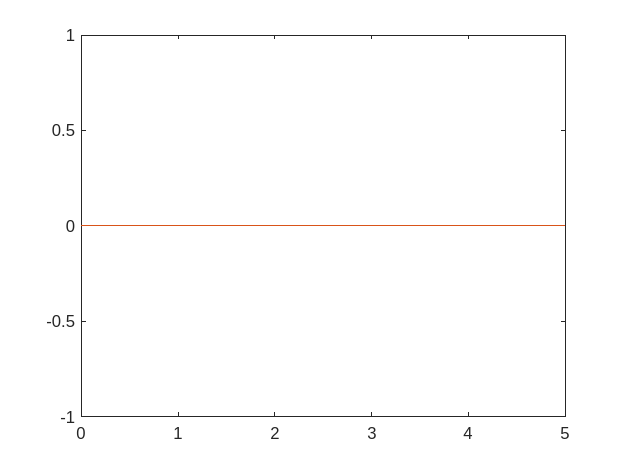

time = 0:Ts:5;
zero_input = zeros(length(time), 1);
zero_response = lsim(Gest, zero_input, time);
zero_response_new = lsim(Gest_new, zero_input, time);

plot(time, [zero_input, zero_response])

plot(time, [zero_input, zero_response_new])

extract complete data in case the normal data is cut off

Compare with initial conditions as potentially zero

function myCompare(myData, myGest, initialCondZero)
    opt = compareOptions;
    if initialCondZero
        opt.InitialCondition = 'zero';
    end
    compare(myData, myGest, opt);  
end

cutoff transitory response

function result = cutoffBeginning(dataStruct, Ts, secondsToCutOff)
    if secondsToCutOff > 0
    dataStruct.data_crane_complete = dataStruct.data_crane;
    dataStruct.data_crane = dataStruct.data_crane(1:end, round(secondsToCutOff / Ts) + 1 : end);
    end
    result = dataStruct;
end